# Exercise 2

## Avoiding Obstacle with Potentials

### About This Exercise

So far, you've developed control methods that drive the robot straight towards the goal. However, what if we know there is an obstacle between the robot and the goal? Going back to the sledding analogy, if there was a tree between us and the bottom of the hill, we would want to adjust our control to avoid it. We can build a potential function for our tree, or any obstacle, where it grows very quickly as we approach the edges of the obstacle. We are basically building a very steep hill right around the tree that will repel the sled if it gets too close.

The nice thing about potential functions is that we can simply add them together and use the gradient of the summed potential function to command our robot. In this exercise, you will first write a potential function for an obstacle. Then you will visualize how the potential function changes as you add the obstacle potential to your previous bowl potential. Then you will simulate a holonomic robot as it navigates toward the goal around an obstacle using the combined potential functions.

**By the end of this exercise, you'll be able to: **

- **Move a robot towards a goal while avoiding obstacles using obstacle potentials.**

### Towering monolith

First we need to write functions that will calculate the potential and gradients at input points for a given polygon representing the boundary of an obstacle. 

[► Write the obstacle potential function](matlab:open('./obstaclePotential.mlx'))

Once complete, follow the section below to calculate and visualize the potential function being added to the quadratic potential function from the previous exercise.

#### Calculate and Visualize

- Set the goal and parameters C and Q.

goal_x = 0;
goal_y = 0;
C = .5; %Change Value Here [0, 1]
Q = 5.8; %Change Value Here [1,10]

- Create a polygon that approximates a circle centered at [2,2]. The polygon's first column contains the x coordinates and the second contains the y coordinates. 

center = [2,2];
radius = 0.4; %Change Value Here [.1, .5]
th = linspace(0,2*pi,21);
poly = [center(1)+radius*cos(th(1:end-1)'),center(2)+radius*sin(th(1:end-1)')];

- Now we will use both the quadraticPotential and obstaclePotential functions to create two potentials.

dx = 0.1;
x = -4:dx:4;
y = x;
[X,Y] = meshgrid(x,y);
[Ugoal, dUdxgoal, dUdygoal] = quadraticPotential(X,Y,[goal_x,goal_y],C);
[Uobs,dUdxobs,dUdyobs] = obstaclePotential(X,Y,poly,C,Q);

- Combine potentials

U = Ugoal + Uobs;
dUdx = dUdxgoal + dUdxobs;
dUdy = dUdygoal + dUdyobs;

- Plot potentials. Left shows the obstacle potential, and the right shows the combined potential. 

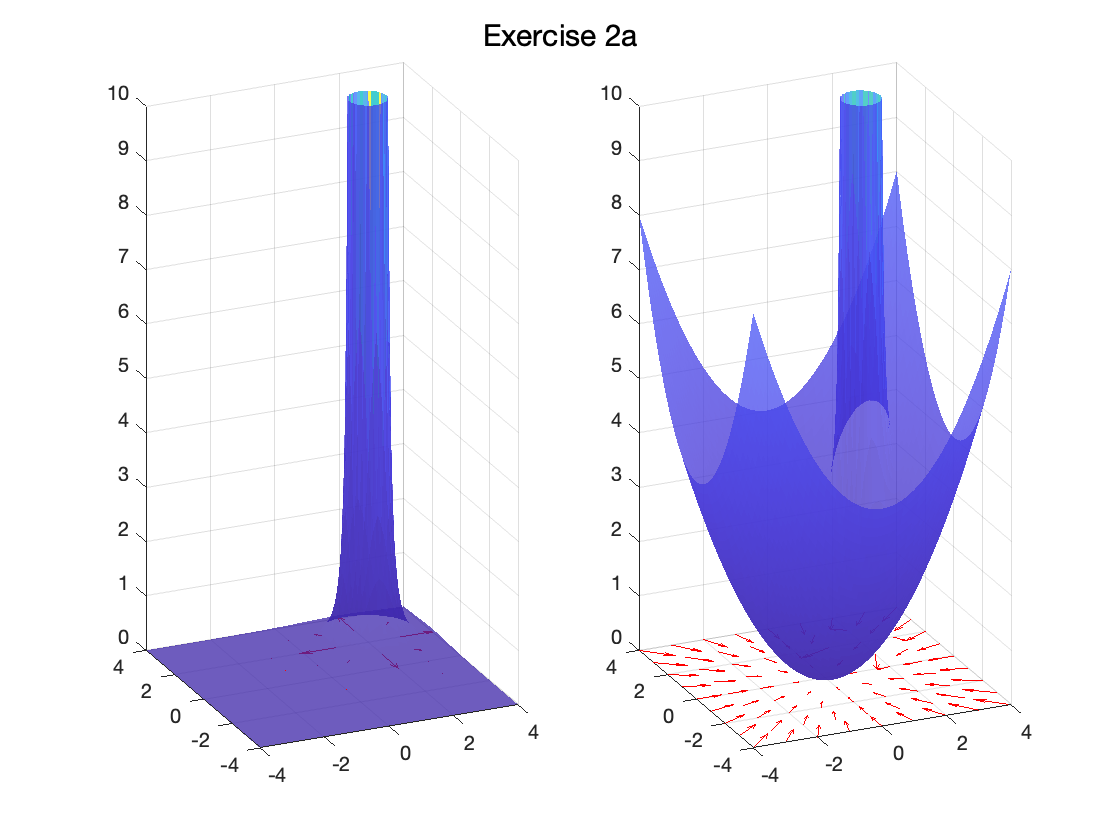

plot_title = "Exercise 2a"; 
[indx, indy] = plotPotentials(dUdxobs, dUdyobs, X, Y, Uobs,U, dUdx, dUdy, plot_title);

This function will animate the robot using the control derived from the potential function trying to navigate to the goal (denoted by the cyan asterisk).  What happens if the obstacle is directly inbetween the start and goal position (set the start_x and start_y = 3). What happens as you adjust the value for Q from a small to larger value? Why?

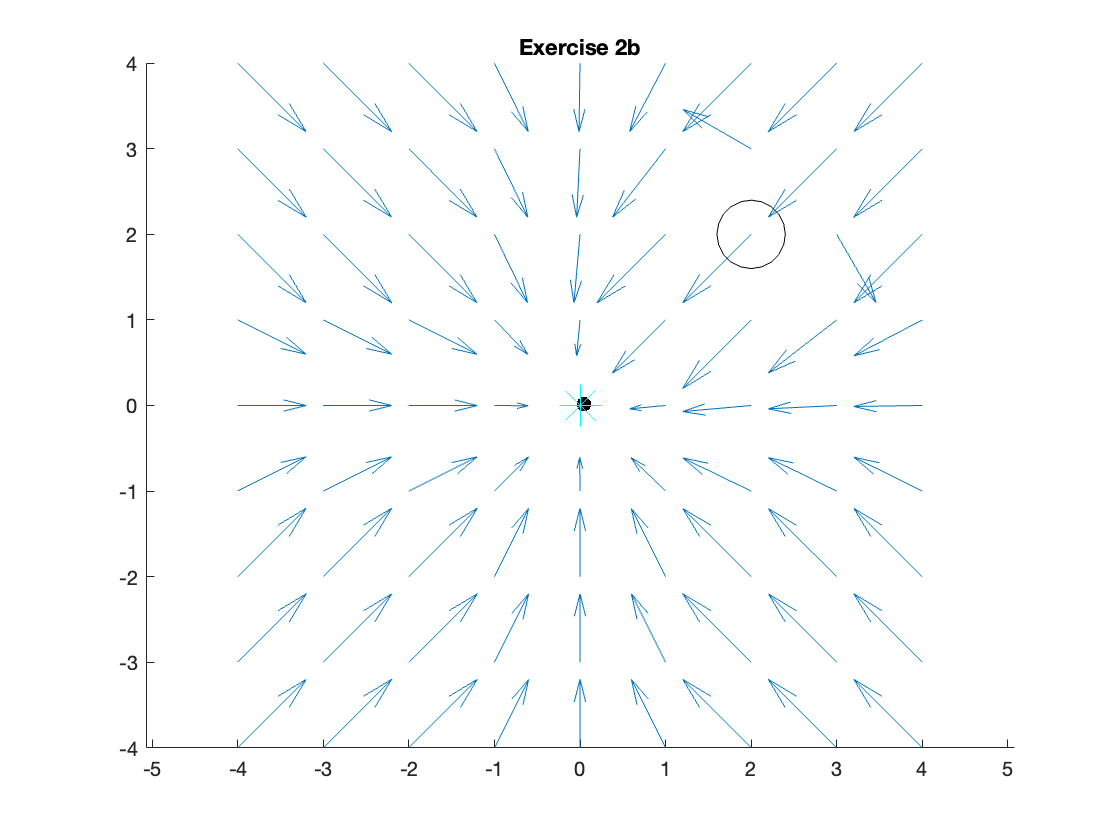

start_x = 3.8;
start_y = 3.5;
plot_title = "Exercise 2b"; 
animate_robot2(X, indx, indy, Y, dUdx, dUdy, start_x, start_y, goal_x, goal_y, C,poly, plot_title);

### Finished!

Now that you have built a general function for a goal potential and an obstacle potential, you have the ability to combine them to drive the robot towards a goal while avoiding obstacles. In the next exercises, we will look at some of the issues that can arise from this method as we add more obstacles.